clear all,close all,clc
d1 = load('Snooze.txt');
d2 = load('Rock.txt');
d3 = load('Paper.txt');
d4 = load('Scissor.txt');
d = [d1, d2, d3, d4];
size(d)

ans =            2       96120


fE.featuresCell = {'MAV'};
fE.LW = 128;
fE.LI = 64;

sampleX1 = Rawdata2SampleMatrix(d1, fE);
sampleX2 = Rawdata2SampleMatrix(d2, fE);
sampleX3 = Rawdata2SampleMatrix(d3, fE);
sampleX4 = Rawdata2SampleMatrix(d4, fE);
size(sampleX1)

ans =    374     2


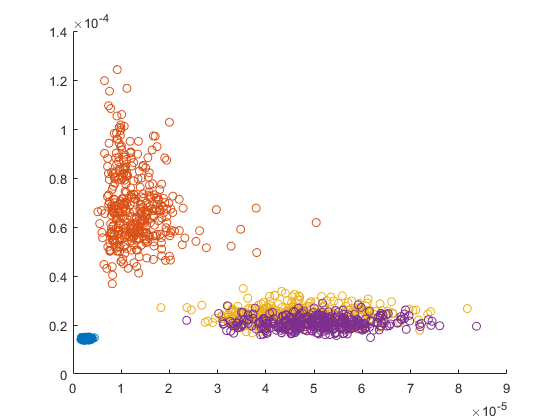

figure;
% - Snooze
scatter(sampleX1(:, 1), sampleX1(:,2));hold on;
% - Rock
scatter(sampleX2(:, 1), sampleX2(:,2));hold on;
% - Paper
scatter(sampleX3(:, 1), sampleX3(:,2));hold on;
% - Scissor
scatter(sampleX4(:, 1), sampleX4(:,2));hold on;

Summary:

由此可见，针对Paper与Scissors的区分，还需要找其他的不同点：

1. 肌肉的粘贴位置不同，在信号源上找不同；

2. 提取不同的特征，探索更多的特征；

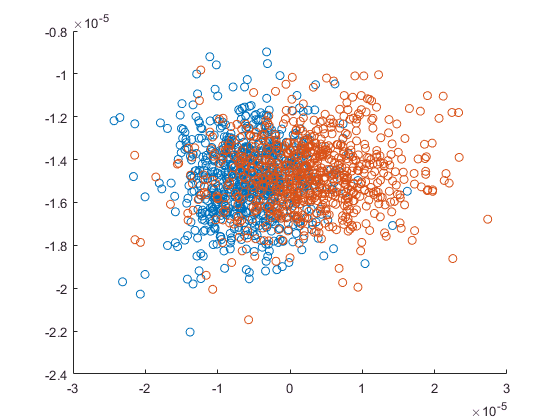

fE.featuresCell = {'PSD'};
fE.LW = 128;
fE.LI = 32;
sampleX3 = Rawdata2SampleMatrix(d3, fE);
sampleX4 = Rawdata2SampleMatrix(d4, fE);

figure;
% - Paper
scatter(sampleX3(:, 1), sampleX3(:,2));hold on;
% - Scissor
scatter(sampleX4(:, 1), sampleX4(:,2));hold on;